rect = @(t) double(abs(t) <= 0.5);
f = @(t) 3*rect(t/2) + rect(t);

%For continous functions
function result=general_fourier_transform (f)
    result= @(omega) integral(@(t) f(t) .* exp(-1j * omega * t), -inf,inf, 'ArrayValued', true);
end

%For discrete or high oscillatory integrals (for example exp(-j*A(t))
function result=general_fourier_transform_discrete (f)
    t = linspace(-10, 10, 10000); 
    f_discrete = f(t);
    result= @(omega) trapz(t, f_discrete.* exp(-1j * omega * t));
end

omega = linspace(-20, 20, 1000);
F_omega = arrayfun(general_fourier_transform(f), omega);

plot(omega, F_omega);

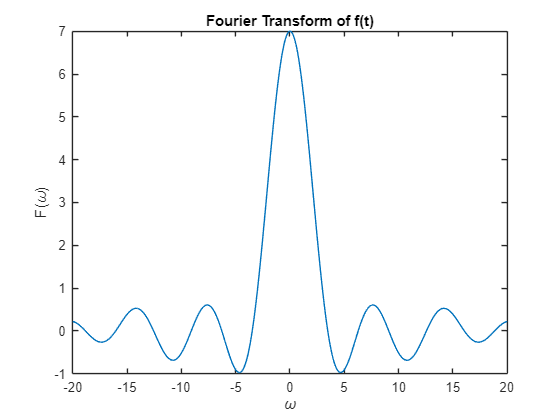

title('Fourier Transform of f(t)');
xlabel('\omega');
ylabel('F(\omega)');


g =@(t) exp(-1j*6*pi*t);
G_omega = arrayfun(general_fourier_transform_discrete(g),omega);

plot(omega, G_omega);

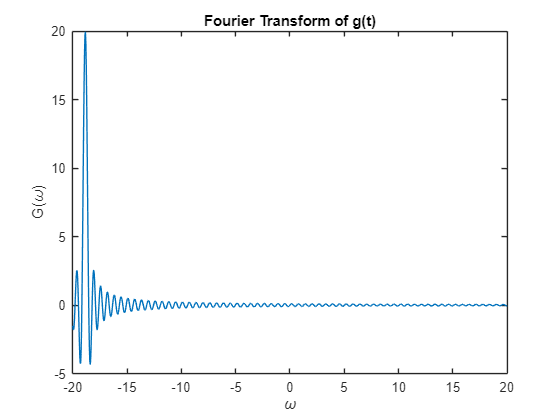

title('Fourier Transform of g(t)');
xlabel('\omega');
ylabel('G(\omega)');

fg=@(t) exp(-1j*6*pi*t)*(3*rect(t/2) + rect(t));
FG_Omega=arrayfun(general_fourier_transform(fg), omega);
plot(omega,FG_Omega);

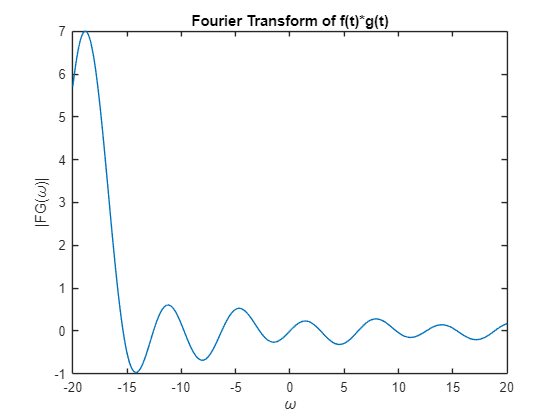

title('Fourier Transform of f(t)*g(t)');
xlabel('\omega');
ylabel('|FG(\omega)|');

plot(omega,F_omega.*G_omega);

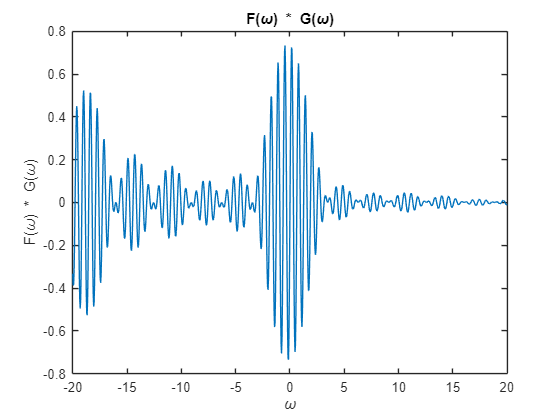

title('F(\omega) * G(\omega)');
xlabel('\omega');
ylabel('F(\omega) * G(\omega)');